%% GPR Bifurcation Demo (refactored with local helpers)
close all; clear;

% (Keep your existing GP helpers for now)
addpath(fullfile("GPR_FUNCS"));

%% Load Data
load("data_save.mat");  % 'data' = [forcing_amp, forcing_freq, response_amp]
forcing_amp   = data(:, 1);   % y (what we predict)
forcing_freq  = data(:, 2);   % x1
response_amp  = data(:, 3);   % x2

X_data = [forcing_freq, response_amp];   % n×2  [FF, RR]
y_data = forcing_amp;                    % n×1

%% Grid (query domain)
freq_range = linspace(min(forcing_freq), max(forcing_freq), 50);
resp_range = linspace(min(response_amp), 1.7, 50);
[FF, RR]   = meshgrid(freq_range, resp_range);              % size mR×mF
X_query    = [FF(:), RR(:)];                                % m×2 (m = numel(FF))
% Spacings and cell area (for area-weighted metrics)
[dFF, dRR, dA] = compute_grid_area(freq_range, resp_range);

% --- Seed training set (tiny to start the loop) ---
training_idx = randperm(length(y_data), 10);
X_train = X_data(training_idx, :);
y_train = y_data(training_idx);

%% Fit GPR
gpr_model = fitrgp(X_train, y_train, ...
    'KernelFunction', 'ardsquaredexponential', ...
    'Standardize', true);

%% Quick surface from MATLAB predict (for visual only)
[Y_pred, Y_std] = predict(gpr_model, X_query);
AA  = reshape(Y_pred, size(RR));     % mean surface (forcing amp)
STD = reshape(Y_std,  size(RR));     % obs std surface

Best candidate: [FF, RR] = [0.2776, 0.7874],  E[Δ] = 0.007


IV=0.0483,  A_p=0.00361,  H=0.019,  U_D=0.726,  E[Δ]=0.007 (±0.00496),  EIVR=0.0239,  ||g||_1=0.103,  ||g_D||_1=0.68,  max|g_D|=5.88,  s2*=0.367,  d_min(std)=0.502,  time=3.91s


training_idx =    360   399    56   401   277    43   122   238   415   417   173


Best candidate: [FF, RR] = [0.3224, 1.159],  E[Δ] = 0.005116


IV=0.0221,  A_p=0.00397,  H=0.0189,  U_D=0.429,  E[Δ]=0.00512 (±0.00326),  EIVR=0.00906,  ||g||_1=0.0875,  ||g_D||_1=0.61,  max|g_D|=5.81,  s2*=0.151,  d_min(std)=0.273,  time=3.79s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260


Best candidate: [FF, RR] = [0.3837, 1.092],  E[Δ] = 0.003059


IV=0.00897,  A_p=0.00588,  H=0.0205,  U_D=0.127,  E[Δ]=0.00306 (±0.00213),  EIVR=0.00654,  ||g||_1=0.101,  ||g_D||_1=0.253,  max|g_D|=1.96,  s2*=0.118,  d_min(std)=0.969,  time=4.22s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410


Best candidate: [FF, RR] = [0.2163, 0.4832],  E[Δ] = 0.002395


IV=0.00349,  A_p=0.0112,  H=0.0345,  U_D=0.0941,  E[Δ]=0.0024 (±0.0016),  EIVR=0.00154,  ||g||_1=0.0819,  ||g_D||_1=0.28,  max|g_D|=4.22,  s2*=0.0312,  d_min(std)=0.502,  time=4.05s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46


Best candidate: [FF, RR] = [0.2735, 1.531],  E[Δ] = 0.001659


IV=0.00176,  A_p=0.00686,  H=0.0184,  U_D=0.0601,  E[Δ]=0.00166 (±0.00105),  EIVR=0.000595,  ||g||_1=0.12,  ||g_D||_1=0.35,  max|g_D|=6.64,  s2*=0.00802,  d_min(std)=0.422,  time=4.10s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160


Best candidate: [FF, RR] = [0.3102, 0.179],  E[Δ] = 0.004181


IV=0.0494,  A_p=0.0071,  H=0.0323,  U_D=0.372,  E[Δ]=0.00418 (±0.00222),  EIVR=0.0161,  ||g||_1=0.0645,  ||g_D||_1=0.199,  max|g_D|=2.42,  s2*=0.469,  d_min(std)=0.466,  time=3.27s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233


Best candidate: [FF, RR] = [0.2204, 0.9564],  E[Δ] = 0.003921


IV=0.0262,  A_p=0.00747,  H=0.0323,  U_D=0.279,  E[Δ]=0.00392 (±0.00236),  EIVR=0.00618,  ||g||_1=0.0507,  ||g_D||_1=0.183,  max|g_D|=2.6,  s2*=0.257,  d_min(std)=0.539,  time=3.48s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50


Best candidate: [FF, RR] = [0.2857, 0.1114],  E[Δ] = 0.002896


IV=0.0119,  A_p=0.00849,  H=0.0294,  U_D=0.149,  E[Δ]=0.0029 (±0.00204),  EIVR=0.00296,  ||g||_1=0.0871,  ||g_D||_1=0.234,  max|g_D|=2.31,  s2*=0.0619,  d_min(std)=0.385,  time=3.95s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190


Best candidate: [FF, RR] = [0.2449, 1.261],  E[Δ] = 0.002588


IV=0.00768,  A_p=0.00809,  H=0.0264,  U_D=0.123,  E[Δ]=0.00259 (±0.00169),  EIVR=0.00236,  ||g||_1=0.1,  ||g_D||_1=0.257,  max|g_D|=3.02,  s2*=0.0381,  d_min(std)=0.457,  time=4.25s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115


Best candidate: [FF, RR] = [0.3265, 0.04376],  E[Δ] = 0.00118


IV=0.00436,  A_p=0.00823,  H=0.0239,  U_D=0.094,  E[Δ]=0.00118 (±0.000768),  EIVR=0.000615,  ||g||_1=0.0502,  ||g_D||_1=0.203,  max|g_D|=4.91,  s2*=0.0296,  d_min(std)=0.342,  time=4.01s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274


Best candidate: [FF, RR] = [0.3224, 1.43],  E[Δ] = 0.00132


IV=0.00633,  A_p=0.0089,  H=0.0274,  U_D=0.0987,  E[Δ]=0.00132 (±0.000974),  EIVR=0.00156,  ||g||_1=0.0621,  ||g_D||_1=0.145,  max|g_D|=1.98,  s2*=0.0375,  d_min(std)=0.43,  time=3.98s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262


Best candidate: [FF, RR] = [0.3306, 1.7],  E[Δ] = 0.00154


IV=0.00666,  A_p=0.01,  H=0.0324,  U_D=0.107,  E[Δ]=0.00154 (±0.0011),  EIVR=0.000565,  ||g||_1=0.0267,  ||g_D||_1=0.0855,  max|g_D|=1.63,  s2*=0.0711,  d_min(std)=0.449,  time=4.21s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286


Best candidate: [FF, RR] = [0.2449, 0.348],  E[Δ] = 0.001118


IV=0.00537,  A_p=0.00951,  H=0.0287,  U_D=0.0894,  E[Δ]=0.00112 (±0.000716),  EIVR=0.00073,  ||g||_1=0.0573,  ||g_D||_1=0.09,  max|g_D|=1.09,  s2*=0.0317,  d_min(std)=0.483,  time=4.19s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87


Best candidate: [FF, RR] = [0.2082, 0.4156],  E[Δ] = 0.0007174


IV=0.00473,  A_p=0.0103,  H=0.0305,  U_D=0.0885,  E[Δ]=0.000717 (±0.000454),  EIVR=0.000319,  ||g||_1=0.0304,  ||g_D||_1=0.0503,  max|g_D|=1.49,  s2*=0.0321,  d_min(std)=0.256,  time=4.02s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24


Best candidate: [FF, RR] = [0.2041, 1.024],  E[Δ] = 0.0006135


IV=0.00402,  A_p=0.0104,  H=0.0298,  U_D=0.0825,  E[Δ]=0.000614 (±0.000494),  EIVR=0.000246,  ||g||_1=0.0282,  ||g_D||_1=0.0484,  max|g_D|=1.25,  s2*=0.0313,  d_min(std)=0.256,  time=4.03s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9


Best candidate: [FF, RR] = [0.2, 0.1114],  E[Δ] = 0.000556


IV=0.00348,  A_p=0.011,  H=0.0302,  U_D=0.0772,  E[Δ]=0.000556 (±0.000373),  EIVR=8.89e-05,  ||g||_1=0.0136,  ||g_D||_1=0.0303,  max|g_D|=1.09,  s2*=0.0362,  d_min(std)=0.311,  time=4.06s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1


Best candidate: [FF, RR] = [0.3633, 0.8212],  E[Δ] = 0.0004357


IV=0.00315,  A_p=0.0108,  H=0.029,  U_D=0.0746,  E[Δ]=0.000436 (±0.000318),  EIVR=0.000425,  ||g||_1=0.0487,  ||g_D||_1=0.103,  max|g_D|=1.27,  s2*=0.0232,  d_min(std)=0.568,  time=4.25s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365


Best candidate: [FF, RR] = [0.2, 0.517],  E[Δ] = 0.0003884


IV=0.0026,  A_p=0.011,  H=0.029,  U_D=0.0684,  E[Δ]=0.000388 (±0.000321),  EIVR=3.83e-05,  ||g||_1=0.0158,  ||g_D||_1=0.041,  max|g_D|=1.5,  s2*=0.0152,  d_min(std)=0.24,  time=4.10s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4


Best candidate: [FF, RR] = [0.2041, 1.328],  E[Δ] = 0.0004117


IV=0.00236,  A_p=0.0111,  H=0.0282,  U_D=0.0643,  E[Δ]=0.000412 (±0.000258),  EIVR=8.92e-05,  ||g||_1=0.0217,  ||g_D||_1=0.0431,  max|g_D|=1.24,  s2*=0.0136,  d_min(std)=0.297,  time=4.19s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13


Best candidate: [FF, RR] = [0.2, 1.666],  E[Δ] = 0.0004071


IV=0.0021,  A_p=0.0112,  H=0.0279,  U_D=0.0614,  E[Δ]=0.000407 (±0.000332),  EIVR=0.00011,  ||g||_1=0.0134,  ||g_D||_1=0.0472,  max|g_D|=2.3,  s2*=0.0483,  d_min(std)=0.421,  time=4.56s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19


Best candidate: [FF, RR] = [0.3633, 1.666],  E[Δ] = 0.0003744


IV=0.00208,  A_p=0.0115,  H=0.0284,  U_D=0.0593,  E[Δ]=0.000374 (±0.000227),  EIVR=0.000346,  ||g||_1=0.041,  ||g_D||_1=0.0747,  max|g_D|=1.1,  s2*=0.022,  d_min(std)=0.485,  time=4.29s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370


Best candidate: [FF, RR] = [0.2531, 0.1452],  E[Δ] = 0.0003619


IV=0.00204,  A_p=0.0125,  H=0.032,  U_D=0.0616,  E[Δ]=0.000362 (±0.000275),  EIVR=5.86e-05,  ||g||_1=0.0192,  ||g_D||_1=0.0451,  max|g_D|=0.587,  s2*=0.0153,  d_min(std)=0.428,  time=4.25s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106


Best candidate: [FF, RR] = [0.298, 1.7],  E[Δ] = 0.0002787


IV=0.00188,  A_p=0.0123,  H=0.0311,  U_D=0.0599,  E[Δ]=0.000279 (±0.000193),  EIVR=4.17e-05,  ||g||_1=0.0184,  ||g_D||_1=0.0511,  max|g_D|=0.877,  s2*=0.0149,  d_min(std)=0.454,  time=4.08s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224


Best candidate: [FF, RR] = [0.4, 0.517],  E[Δ] = 0.0002525


IV=0.0019,  A_p=0.0122,  H=0.0306,  U_D=0.0593,  E[Δ]=0.000252 (±0.000178),  EIVR=0.000334,  ||g||_1=0.0235,  ||g_D||_1=0.061,  max|g_D|=2.27,  s2*=0.0523,  d_min(std)=0.561,  time=4.21s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426


Best candidate: [FF, RR] = [0.2571, 0.9226],  E[Δ] = 0.0005902


IV=0.00149,  A_p=0.0119,  H=0.0298,  U_D=0.0549,  E[Δ]=0.00059 (±0.000464),  EIVR=6.41e-05,  ||g||_1=0.0281,  ||g_D||_1=0.0652,  max|g_D|=0.632,  s2*=0.0112,  d_min(std)=0.436,  time=4.22s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132


Best candidate: [FF, RR] = [0.2776, 0.3818],  E[Δ] = 0.0004867


IV=0.00168,  A_p=0.0118,  H=0.0302,  U_D=0.0589,  E[Δ]=0.000487 (±0.00037),  EIVR=6.02e-05,  ||g||_1=0.0239,  ||g_D||_1=0.0723,  max|g_D|=1.48,  s2*=0.0135,  d_min(std)=0.476,  time=4.06s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171


Best candidate: [FF, RR] = [0.3469, 0.8212],  E[Δ] = 0.0003355


IV=0.00154,  A_p=0.0118,  H=0.0296,  U_D=0.0568,  E[Δ]=0.000336 (±0.000246),  EIVR=6.99e-05,  ||g||_1=0.0277,  ||g_D||_1=0.058,  max|g_D|=0.615,  s2*=0.0125,  d_min(std)=0.339,  time=4.35s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322


Best candidate: [FF, RR] = [0.2041, 0.7874],  E[Δ] = 0.000677


IV=0.000888,  A_p=0.00983,  H=0.0261,  U_D=0.0585,  E[Δ]=0.000677 (±0.000414),  EIVR=1.69e-05,  ||g||_1=0.0178,  ||g_D||_1=0.0888,  max|g_D|=2.32,  s2*=0.00429,  d_min(std)=0.37,  time=4.27s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27


Best candidate: [FF, RR] = [0.2857, 1.328],  E[Δ] = 0.0005058


IV=0.000839,  A_p=0.00991,  H=0.0251,  U_D=0.0553,  E[Δ]=0.000506 (±0.000334),  EIVR=5.84e-05,  ||g||_1=0.0461,  ||g_D||_1=0.136,  max|g_D|=1.58,  s2*=0.00389,  d_min(std)=0.411,  time=4.04s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178


Best candidate: [FF, RR] = [0.3469, 1.362],  E[Δ] = 0.0002803


IV=0.00145,  A_p=0.0132,  H=0.0316,  U_D=0.0522,  E[Δ]=0.00028 (±0.000179),  EIVR=6.75e-05,  ||g||_1=0.0242,  ||g_D||_1=0.052,  max|g_D|=0.823,  s2*=0.0138,  d_min(std)=0.403,  time=4.10s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304


Best candidate: [FF, RR] = [0.2, 0.348],  E[Δ] = 0.0003127


IV=0.00133,  A_p=0.0133,  H=0.0313,  U_D=0.05,  E[Δ]=0.000313 (±0.000232),  EIVR=9.04e-06,  ||g||_1=0.00787,  ||g_D||_1=0.024,  max|g_D|=1.07,  s2*=0.0119,  d_min(std)=0.16,  time=4.02s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3


Best candidate: [FF, RR] = [0.2, 0.04376],  E[Δ] = 0.0002581


IV=0.00125,  A_p=0.0134,  H=0.0308,  U_D=0.0487,  E[Δ]=0.000258 (±0.000173),  EIVR=6.3e-06,  ||g||_1=0.00547,  ||g_D||_1=0.0203,  max|g_D|=1.31,  s2*=0.0141,  d_min(std)=0.0531,  time=4.09s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1


Best candidate: [FF, RR] = [0.2531, 1.7],  E[Δ] = 0.0002057


IV=0.00119,  A_p=0.0131,  H=0.03,  U_D=0.048,  E[Δ]=0.000206 (±0.000153),  EIVR=1.14e-05,  ||g||_1=0.00928,  ||g_D||_1=0.0308,  max|g_D|=0.799,  s2*=0.0105,  d_min(std)=0.0628,  time=4.04s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121


Best candidate: [FF, RR] = [0.3633, 1.7],  E[Δ] = 0.0001595


IV=0.00112,  A_p=0.0129,  H=0.0292,  U_D=0.0472,  E[Δ]=0.00016 (±9.69e-05),  EIVR=1.71e-05,  ||g||_1=0.0115,  ||g_D||_1=0.0235,  max|g_D|=0.422,  s2*=0.0101,  d_min(std)=0.106,  time=4.12s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349


Best candidate: [FF, RR] = [0.2, 0.04376],  E[Δ] = 0.0001473


IV=0.00106,  A_p=0.0128,  H=0.0287,  U_D=0.0463,  E[Δ]=0.000147 (±0.000108),  EIVR=2.12e-06,  ||g||_1=0.00408,  ||g_D||_1=0.0176,  max|g_D|=1.2,  s2*=0.00907,  d_min(std)=0.0522,  time=4.06s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1


Best candidate: [FF, RR] = [0.3592, 1.227],  E[Δ] = 0.0001468


IV=0.001,  A_p=0.0126,  H=0.028,  U_D=0.0457,  E[Δ]=0.000147 (±8.93e-05),  EIVR=3.07e-05,  ||g||_1=0.0205,  ||g_D||_1=0.0462,  max|g_D|=0.761,  s2*=0.0085,  d_min(std)=0.332,  time=4.07s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346


Best candidate: [FF, RR] = [0.4, 1.497],  E[Δ] = 0.0001886


IV=0.000374,  A_p=0.00933,  H=0.0168,  U_D=0.0383,  E[Δ]=0.000189 (±0.000166),  EIVR=0.000127,  ||g||_1=0.013,  ||g_D||_1=0.0414,  max|g_D|=2.02,  s2*=0.0307,  d_min(std)=0.516,  time=4.27s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434


Best candidate: [FF, RR] = [0.2, 0.8888],  E[Δ] = 0.0002156


IV=0.000747,  A_p=0.0124,  H=0.0265,  U_D=0.0411,  E[Δ]=0.000216 (±0.000143),  EIVR=5.44e-06,  ||g||_1=0.00787,  ||g_D||_1=0.025,  max|g_D|=0.648,  s2*=0.00657,  d_min(std)=0.219,  time=4.30s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7


Best candidate: [FF, RR] = [0.2, 1.362],  E[Δ] = 0.0001929


IV=0.000714,  A_p=0.0127,  H=0.0264,  U_D=0.0399,  E[Δ]=0.000193 (±0.00013),  EIVR=4.82e-06,  ||g||_1=0.00733,  ||g_D||_1=0.0277,  max|g_D|=1.43,  s2*=0.0063,  d_min(std)=0.0456,  time=4.15s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13


Best candidate: [FF, RR] = [0.2857, 1.024],  E[Δ] = 0.0002568


IV=0.000244,  A_p=0.00928,  H=0.0164,  U_D=0.0352,  E[Δ]=0.000257 (±0.000187),  EIVR=1.59e-05,  ||g||_1=0.0518,  ||g_D||_1=0.218,  max|g_D|=2.82,  s2*=0.00104,  d_min(std)=0.352,  time=4.24s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.2408, 0.2128],  E[Δ] = 0.0003173


IV=0.000292,  A_p=0.00895,  H=0.017,  U_D=0.0423,  E[Δ]=0.000317 (±0.000225),  EIVR=1.11e-05,  ||g||_1=0.0321,  ||g_D||_1=0.225,  max|g_D|=11.5,  s2*=0.00114,  d_min(std)=0.237,  time=4.07s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.3878, 1.294],  E[Δ] = 0.0002761


IV=0.000282,  A_p=0.00887,  H=0.0164,  U_D=0.0405,  E[Δ]=0.000276 (±0.000222),  EIVR=4.98e-05,  ||g||_1=0.0388,  ||g_D||_1=0.194,  max|g_D|=5.25,  s2*=0.00312,  d_min(std)=0.288,  time=4.08s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.302, 0.686],  E[Δ] = 0.0001486


IV=0.000285,  A_p=0.0102,  H=0.0192,  U_D=0.0339,  E[Δ]=0.000149 (±0.000132),  EIVR=1.61e-05,  ||g||_1=0.033,  ||g_D||_1=0.125,  max|g_D|=2.36,  s2*=0.00194,  d_min(std)=0.319,  time=4.07s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.2286, 1.565],  E[Δ] = 0.0001434


IV=0.000333,  A_p=0.011,  H=0.0208,  U_D=0.0336,  E[Δ]=0.000143 (±0.000103),  EIVR=6.45e-06,  ||g||_1=0.0131,  ||g_D||_1=0.0423,  max|g_D|=1.28,  s2*=0.00226,  d_min(std)=0.212,  time=4.76s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.2449, 0.686],  E[Δ] = 0.000266


IV=0.000282,  A_p=0.0105,  H=0.0201,  U_D=0.0332,  E[Δ]=0.000266 (±0.000199),  EIVR=6.81e-06,  ||g||_1=0.0207,  ||g_D||_1=0.0786,  max|g_D|=1.42,  s2*=0.00164,  d_min(std)=0.353,  time=4.62s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.3184, 1.565],  E[Δ] = 0.0001601


IV=0.000248,  A_p=0.0103,  H=0.0189,  U_D=0.0321,  E[Δ]=0.00016 (±0.000125),  EIVR=5.25e-06,  ||g||_1=0.0185,  ||g_D||_1=0.0896,  max|g_D|=2.9,  s2*=0.0014,  d_min(std)=0.276,  time=4.63s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.3959, 1.7],  E[Δ] = 0.0001081


IV=0.000268,  A_p=0.0106,  H=0.0192,  U_D=0.0312,  E[Δ]=0.000108 (±7.13e-05),  EIVR=4.67e-06,  ||g||_1=0.0117,  ||g_D||_1=0.0424,  max|g_D|=2.07,  s2*=0.00238,  d_min(std)=0.263,  time=4.47s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.2286, 0.04376],  E[Δ] = 0.0001233


IV=0.000245,  A_p=0.0105,  H=0.0188,  U_D=0.031,  E[Δ]=0.000123 (±8.98e-05),  EIVR=1.81e-06,  ||g||_1=0.00941,  ||g_D||_1=0.0587,  max|g_D|=3.48,  s2*=0.00164,  d_min(std)=0.139,  time=4.49s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.2, 1.565],  E[Δ] = 0.0001566


IV=0.000219,  A_p=0.0102,  H=0.018,  U_D=0.0305,  E[Δ]=0.000157 (±0.000123),  EIVR=1.45e-06,  ||g||_1=0.0107,  ||g_D||_1=0.0633,  max|g_D|=4.62,  s2*=0.00122,  d_min(std)=0.183,  time=4.60s


training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


Best candidate: [FF, RR] = [0.351, 1.531],  E[Δ] = 0.0001361


IV=0.00021,  A_p=0.0102,  H=0.0177,  U_D=0.0298,  E[Δ]=0.000136 (±0.000112),  EIVR=4.5e-06,  ||g||_1=0.0219,  ||g_D||_1=0.0951,  max|g_D|=2.5,  s2*=0.00107,  d_min(std)=0.325,  time=4.55s


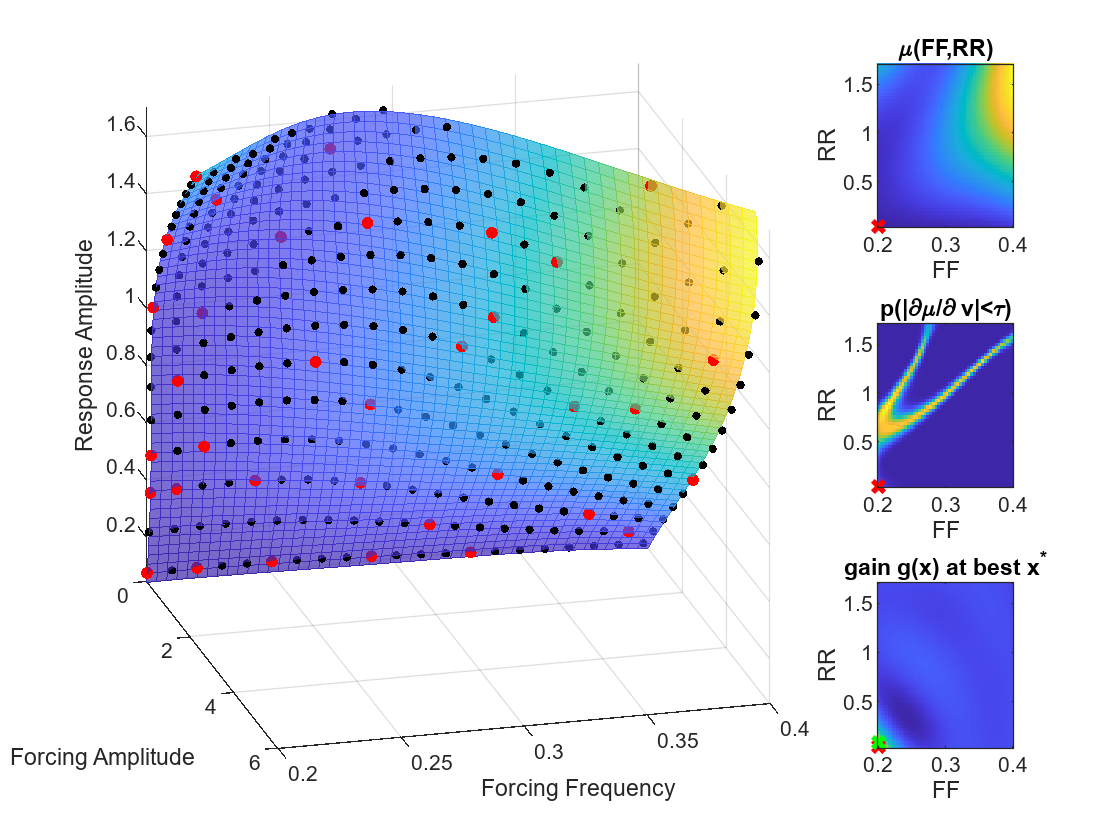

training_idx =    360   399    56   401   277    43   122   238   415   417   173   260   410    46   160   233    50   190   115   274   262   286    87    24     9     1   365     4    13    19   370   106   224   426   132   171   322    27   178   304     3     1   121   349     1   346   434     7    13   196


iterations = 50;
metric_history = {};
for i = 1:iterations
%% Derivative-band caches and baseline fields
params.vdim       = 2;          % derivative along RR (column 2)
params.tau        = 0.05;       % threshold for |∂μ/∂v|
params.R          = 64;         % MC draws per candidate
params.weightMode = 'sigmaD';   % 'none' | 'sigmaD' | 'gain2'
params.Mpick      = 500;        % top-M variance candidates

C     = gpr_build_caches(gpr_model, X_query, params.vdim);
Base  = gpr_baseline_fields(C);

% Baseline soft-band probability over the grid
p0_vec = soft_band_prob(Base.muD, Base.sigD, params.tau);   % m×1
p0m    = reshape(p0_vec, size(FF));

% ===== METRICS: baseline, before picking a candidate =====
M = compute_baseline_metrics(Base, p0_vec, dA);
%% Candidate set (top-M by latent variance)
Xcand = choose_candidates_by_variance(Base, X_query, params.Mpick);

%% Score candidates (expected band change). Track timing + diagnostics for best.
[scores, elapsed_scoring, bestIdx, det_best] = score_candidates( ...
    Xcand, C, Base, params.tau, params.R, params.weightMode);

bestX      = Xcand(bestIdx, :);
bestScore  = scores(bestIdx);
fprintf('Best candidate: [FF, RR] = [%.4g, %.4g],  E[Δ] = %.4g\n', bestX(1), bestX(2), bestScore);

% ===== METRICS: candidate-specific =====
M = compute_candidate_metrics(M, det_best, Base, dA, C, bestX, X_data, training_idx, elapsed_scoring);

% Print a compact summary
summarize_metrics(M);
metric_history{1, i} = M;

%% Visuals: μ, p-band, gain for the best candidate
MU  = reshape(Base.mu, size(FF));
gM  = reshape(det_best.g, size(FF));


% for k = 0:5:360
tiledlayout(3,4, "TileSpacing","tight")
nexttile([3,3]); hold on; grid on;
xlabel("Forcing Amplitude"); ylabel("Forcing Frequency"); zlabel("Response Amplitude");
zlim([min(response_amp), 1.7]);
surf_opt = struct("CData", AA, "FaceAlpha",0.7, "EdgeColor","interp");
surf(AA, FF , RR, surf_opt); %colorbar
scatter3(forcing_amp, forcing_freq, response_amp, 10, "filled", "k")
scatter3(forcing_amp(training_idx), forcing_freq(training_idx), response_amp(training_idx), 20, "filled", "r")
view(75, 20)

nexttile; imagesc(FF(1,:), RR(:,1), MU); axis xy; %colorbar;
title('\mu(FF,RR)'); xlabel('FF'); ylabel('RR'); hold on; plot(bestX(1), bestX(2), 'rx', 'LineWidth', 2);
nexttile; imagesc(FF(1,:), RR(:,1), p0m); axis xy;% colorbar;
title('p(|\partial\mu/\partial v|<\tau)'); xlabel('FF'); ylabel('RR'); hold on; plot(bestX(1), bestX(2), 'rx', 'LineWidth', 2);
nexttile; imagesc(FF(1,:), RR(:,1), gM); axis xy;% colorbar;
title('gain g(x) at best x^*'); xlabel('FF'); ylabel('RR'); hold on; plot(bestX(1), bestX(2), 'rx', 'LineWidth', 2);
% plot_fields_mu_p_gain(MU, p0m, gM, FF, RR, bestX);

%% Map bestX back to nearest feasible test in your dataset (as you had)
[best_index, nextX] = nearest_feasible(bestX, X_data);
plot(nextX(1), nextX(2), 'gx', 'LineWidth', 2);
% pause(5/360*5)
% end


training_idx = [training_idx, best_index]
%% Fit GPR
X_train = X_data(training_idx, :);
y_train = y_data(training_idx);

gpr_model = fitrgp(X_train, y_train, ...
    'KernelFunction', 'ardsquaredexponential', ...
    'Standardize', true);

%% Quick surface from MATLAB predict (for visual only)
[Y_pred, Y_std] = predict(gpr_model, X_query);
AA  = reshape(Y_pred, size(RR));     % mean surface (forcing amp)
STD = reshape(Y_std,  size(RR));     % obs std surface
% From here, your loop would: refit on training_idx, rebuild caches, log M per iteration.


pause(0.1)
end

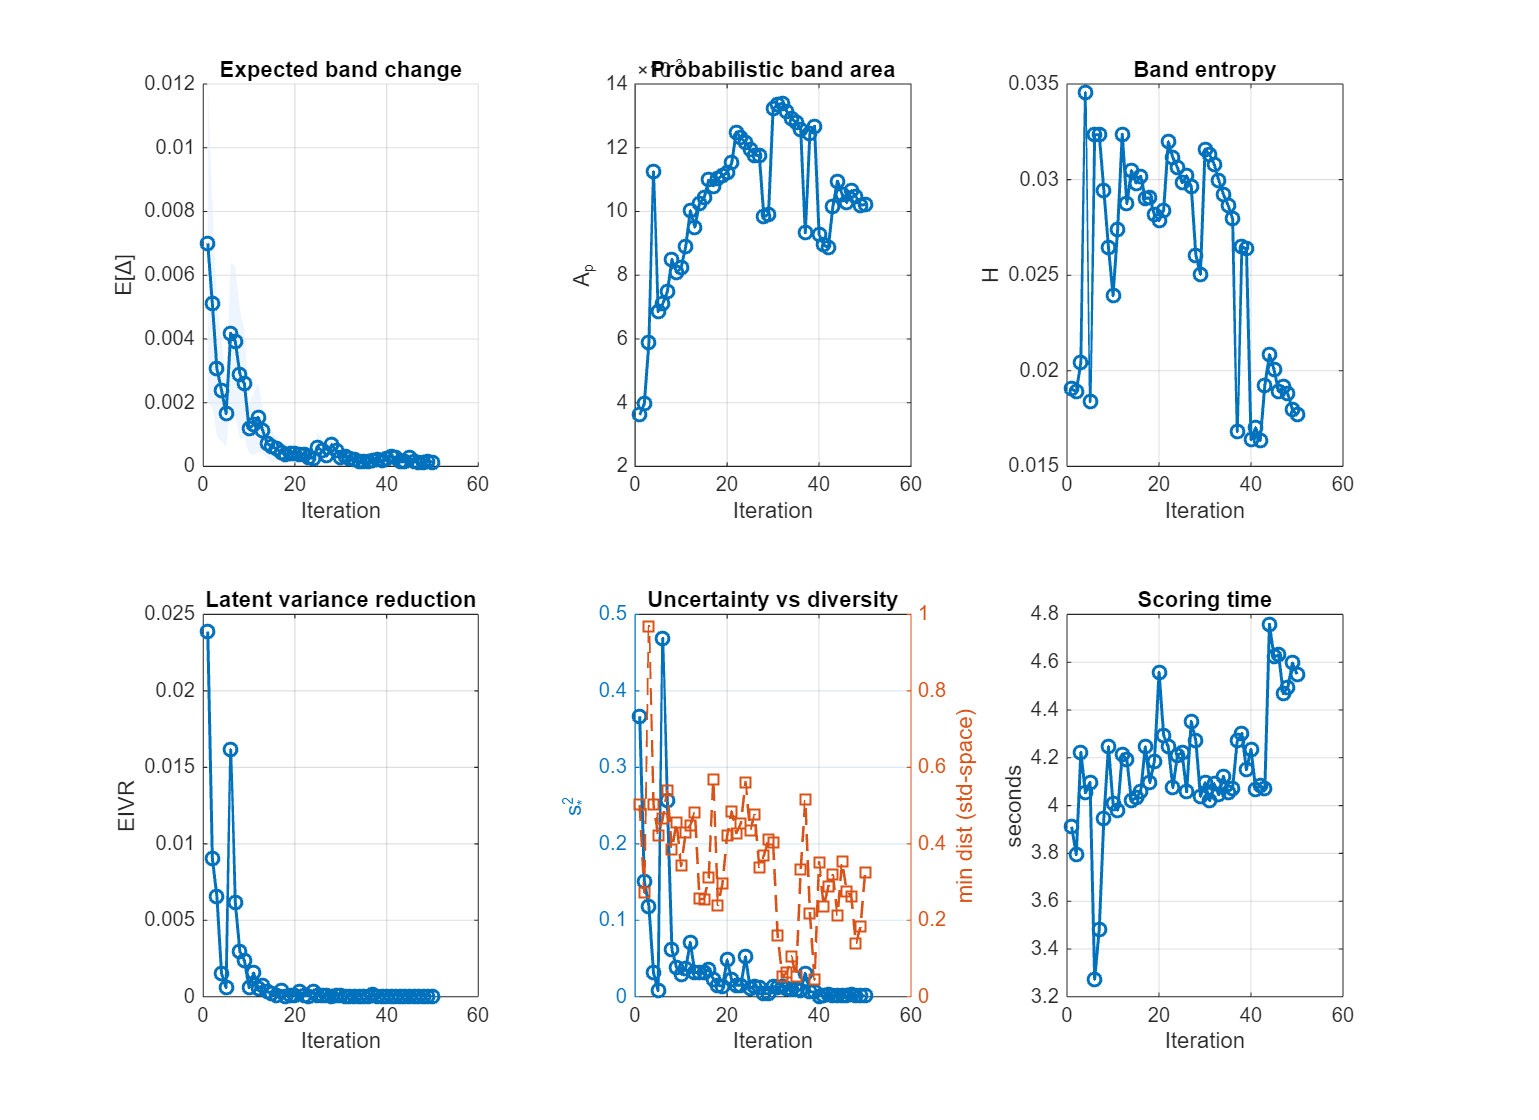

% ===== Plot dashboard from metric_history (cell array of structs) =====
% Expects fields: IV, A_p, H_band, EDelta_best, EDelta_std, EIVR,
%                 s2_candidate, min_dist_std, time_scoring

T  = numel(metric_history);
t  = 1:T;

% Helper to pull a vector out of the history
getv = @(f) cellfun(@(s) s.(f), metric_history);

ED   = getv('EDelta_best');
EDsd = getv('EDelta_std');
Ap   = getv('A_p');
H    = getv('H_band');
EIVR = getv('EIVR');
s2   = getv('s2_candidate');
dmin = getv('min_dist_std');
tt   = getv('time_scoring');

figure('Name','Bifurcation Dashboard','Color','w','Position',[100 100 1100 800]);

% 1) E[Δ] with MC band (if T>1)
subplot(2,3,1);
if T>=2 && any(EDsd>0)
    fill_shaded(t, ED-EDsd, ED+EDsd, [0.88 0.92 1]); hold on;
end
plot(t, ED, '-o','LineWidth',1.4); grid on;
xlabel('Iteration'); ylabel('E[\Delta]'); title('Expected band change');

% 2) A_p
subplot(2,3,2);
plot(t, Ap, '-o','LineWidth',1.4); grid on;
xlabel('Iteration'); ylabel('A_p'); title('Probabilistic band area');

% 3) H (entropy)
subplot(2,3,3);
plot(t, H, '-o','LineWidth',1.4); grid on;
xlabel('Iteration'); ylabel('H'); title('Band entropy');

% 4) EIVR
subplot(2,3,4);
plot(t, EIVR, '-o','LineWidth',1.4); grid on;
xlabel('Iteration'); ylabel('EIVR'); title('Latent variance reduction');

% 5) s^2_* and min distance (right axis)
subplot(2,3,5);
yyaxis left;  plot(t, s2, '-o','LineWidth',1.4); ylabel('s^2_*');
yyaxis right; plot(t, dmin, '--s','LineWidth',1.2); ylabel('min dist (std-space)');
xlabel('Iteration'); title('Uncertainty vs diversity'); grid on;

% 6) runtime
subplot(2,3,6);
plot(t, tt, '-o','LineWidth',1.4); grid on;
xlabel('Iteration'); ylabel('seconds'); title('Scoring time');


% --- local shaded-band helper (kept small; works if x is monotone) ---
function fill_shaded(x, ylo, yhi, rgb)
    x = x(:); ylo = ylo(:); yhi = yhi(:);
    patch([x; flipud(x)], [ylo; flipud(yhi)], rgb, ...
          'EdgeColor','none','FaceAlpha',0.5);
    hold on;
end






